# MAS416 - Mechanical test level 2

## System 14

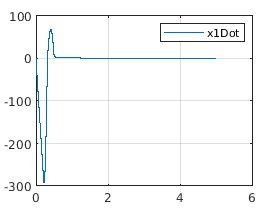

clc; clear all; close all;

m1 = 457; % kg
m2 = 61; % kg
g = 9.81; % m/s^2

k1 = 190000; % N/m
L01 = 115/10^3; % m
b1 = 6000; % N*s/m^1.5

theta = deg2rad(48); % rad

v01 = 10/10^3; % m/s

muk1 = 0.4;

x1 = 145/10^3; % m
x1Dot = 0; % m/s

t = 0; % s
simTime = 5; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculation

    delta = L01-x1;
    deltaDot = -x1Dot;

    if(delta>=0)
        Fb1 = b1*sqrt(delta)*deltaDot;
        Fk1 = k1*delta;
    else
        Fb1 = 0;
        Fk1 = 0;
    end
    Fg1 = m1*g*sin(theta);
    Fg2 = m2*g;

    if(x1Dot < -v01)
        mu = -muk1;
    elseif(x1Dot <= v01)
        mu = muk1*x1Dot/(v01);
    else
        mu = muk1;
    end

    Ffr = m1*g*cos(theta)*mu;

    sumF = Fk1+Fb1-Fg1-Ffr+2*Fg2;

    x1DotDot = sumF/(m1+4*m2);

    % Logging
    t_plt(idx) = t;
    x1Dot_plt(idx) = x1Dot;
    x1_plt(idx) = x1;
    mu_plt(idx) = mu;
    Fk1_plt(idx) = Fk1;

    % Time integration
    x1Dot = x1Dot + x1DotDot * dt;
    x1 = x1 + x1Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x1Dot_plt*1000)
legend("x1Dot")
grid

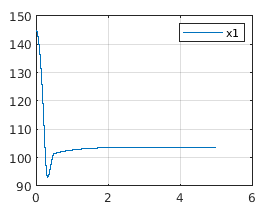

plot(t_plt, x1_plt*1000);
legend("x1")
grid

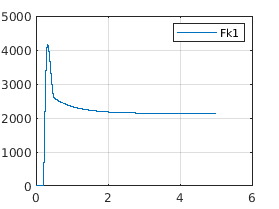


plot(t_plt, Fk1_plt);
legend("Fk1")
grid
hold off

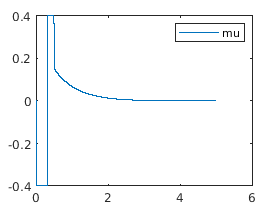

plot(t_plt, mu_plt);
legend("mu")


x1Dot_max = abs(max(x1Dot_plt*1000))

x1Dot_max =           68.2713053098391


x1Dot_min = abs(min(x1Dot_plt*1000))

x1Dot_min =           292.523581052784


disp("What is the maximum absolute value of the velocity [mm/s] of body m1 ?")

What is the maximum absolute value of the velocity [mm/s] of body m1 ?


% Correct solutions :)